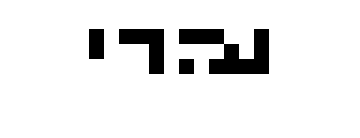

braille = imread('test3.png');
imshow('test3.png', 'InitialMagnification', 1500)


brailleBW = rgb2gray(braille); % to only have 1 dimension
brailleBW(brailleBW==0) = 1; % changes 0 to 1
brailleBW(brailleBW==255) = 0; % changes 255 to 0

[rows, columns] = size(brailleBW); 


%divide matrix into rows of 5 and columns of 3 

c1 = columns / 2; %finds amount of columns
r1 = rows / 3; % finds amount of rows

ro = size(brailleBW, 1) / r1 * ones(1, r1); % creats a vector that is the same length as r and adds to rows
co = size(brailleBW, 2) / c1 * ones(1, c1); % creats a vector that is the same length as c and adds to columns

letter = mat2cell(brailleBW, ro, co) % splits image into smaller matrices of each letter

letter = 1×6 cell array
    {3×2 uint8}    {3×2 uint8}    {3×2 uint8}    {3×2 uint8}    {3×2 uint8}    {3×2 uint8}


used the alphabet from this [https://www.pharmabraille.com/pharmaceutical-braille/the-braille-alphabet/](https://www.pharmabraille.com/pharmaceutical-braille/the-braille-alphabet/) website for the following code.

% make a list of each character in matrix form
A = [1 0; 0 0; 0 0];
B = [1 0; 1 0; 0 0];
C = [1 1; 0 0; 0 0];
D = [1 1; 0 1; 0 0];
E = [1 0; 0 1; 0 0];
F = [1 1; 1 0; 0 0];
G = [1 1; 1 1; 0 0];
H = [1 0; 1 1; 0 0];
I = [0 1; 1 0; 0 0];
J = [0 1; 1 1; 0 0];
K = [1 0; 0 0; 1 0];
L = [1 0; 1 0; 1 0];
M = [1 1; 0 0; 1 0];
N = [1 1; 0 1; 1 0];
O = [1 0; 0 1; 1 0];
P = [1 1; 1 0; 1 0];
Q = [1 1; 1 1; 1 0];
R = [1 0; 1 1; 1 0];
S = [0 1; 1 0; 1 0];
T = [0 1; 1 1; 1 0];
U = [1 0; 0 0; 1 1];
V = [1 0; 1 0; 1 1];
W = [0 1; 1 1; 0 1];
X = [1 1; 0 0; 1 1];
Y = [1 1; 0 1; 1 1];
Z = [1 0; 0 1; 1 1];
Pause = [0 0; 0 0; 0 0];
Hash = [0 1; 0 1; 1 1];


 %compare it to the split cells. 
  words = zeros(r1,c1); %create an array that will store all the numbers corresponding to each letters
 for j1 = 1:c1 %for all the columns of letter cell array
    for i1 = 1:r1 %for all the rows of letter cell array
        %create an if statement loop that recognises each cell as a letter
        %and then assigns a value from 1:26 corresponding to a letter in the alphabet A being 1 and Z being 26.
        %It then stores that value in the correct position in the words
        %array.
           if letter{i1,j1} == A; 
               words(i1,j1) = 1;
           elseif letter{i1,j1} == B;
                words(i1,j1) = 2;
           elseif letter{i1,j1} == C;
                words(i1,j1) = 3;
           elseif letter{i1,j1} == D;
                words(i1,j1) = 4;
           elseif letter{i1,j1} == E;
                words(i1,j1) = 5;
           elseif letter{i1,j1} == F;
                words(i1,j1) = 6;
           elseif letter{i1,j1} == G;
                words(i1,j1) = 7;
           elseif letter{i1,j1} == H;
                words(i1,j1) = 8;
           elseif letter{i1,j1} == I;
                words(i1,j1) = 9;
           elseif letter{i1,j1} == J;
                words(i1,j1) = 10;
           elseif letter{i1,j1} == K;
                words(i1,j1) = 11;
           elseif letter{i1,j1} == L;
                words(i1,j1) = 12;
           elseif letter{i1,j1} == M;
                words(i1,j1) = 13;
           elseif letter{i1,j1} == N;
                words(i1,j1) = 14;
           elseif letter{i1,j1} == O;
                words(i1,j1) = 15;
            elseif letter{i1,j1} == P;
                words(i1,j1) = 16;
            elseif letter{i1,j1} == Q;
                words(i1,j1) = 17;
            elseif letter{i1,j1} == R;
                words(i1,j1) = 18;
            elseif letter{i1,j1} == S;
                words(i1,j1) = 19;
            elseif letter{i1,j1} == T;
               words(i1,j1) = 20;
            elseif letter{i1,j1} == U;
                words(i1,j1) = 21;
            elseif letter{i1,j1} == V;
                words(i1,j1) = 22;
            elseif letter{i1,j1} == W;
                words(i1,j1) = 23;
            elseif letter{i1,j1} == X;
                words(i1,j1) = 24;
           elseif  letter{i1,j1} == Y;
                words(i1,j1) = 25;
           elseif letter{i1,j1} == Z;
                words(i1,j1) = 26;
           elseif letter{i1,j1} == Hash;
                words(i1,j1) = NaN;   
           else letter{i1,j1} == Pause;
                words(i1,j1) = 0;
       
            end
     end
 end
words

words =      2     3    12    13    26   NaN


% a voice read them off
[b,fs] = audioread('b.mp3');, [c,fs] = audioread('c.mp3');, [l,fs] = audioread('l.mp3');, [m,fs] = audioread('m.mp3');,[z,fs] = audioread('z.mp3');
Fs = 35184/1.5; %sampling rate calculated from the size of b divided by some number needed a bit of trial and error to get it right. 
for k1 = 1:length(words)
    if words(k1) == 1; 
               sound(a,Fs)
           elseif words(k1) == 2;
               sound(b,Fs)
               pause(1)
           elseif words(k1) == 3;
                sound(c,Fs)
                pause(1)
           elseif words(k1) == 4;
                sound(d,Fs)
                pause(1)
           elseif words(k1) == 5;
                sound(e,Fs)
                pause(1)
           elseif words(k1) == 6;
                sound(f,Fs)
                pause(1)
           elseif words(k1) == 7;
                sound(g,Fs)
                pause(1)
           elseif words(k1) == 8;
                sound(h,Fs)
                pause(1)
           elseif words(k1) == 9;
                sound(i,Fs)
                pause(1)
           elseif words(k1) == 10;
                sound(j,Fs)
                pause(1)
           elseif words(k1) == 11;
                sound(k,Fs)
                pause(1)
           elseif words(k1) == 12;
              sound(l,Fs)
              pause(1)
           elseif words(k1) == 13;
                sound(m,Fs)
                pause(1)
           elseif words(k1) == 14;
                sound(n,Fs)
                pause(1)
           elseif words(k1) == 15;
                sound(o,Fs)
                pause(1)
            elseif words(k1) == 16;
                sound(p,Fs)
                pause(1)
            elseif words(k1) == 17;
               sound(q,Fs)
               pause(1)
            elseif words(k1) == 18;
                sound(r,Fs)
                pause(1)
            elseif words(k1) == 19;
                sound(s,Fs)
                pause(1)
            elseif words(k1) == 20;
               sound(t,Fs)
               pause(1)
            elseif words(k1) == 21;
                sound(u,Fs)
                pause(1)
            elseif words(k1) == 22;
                sound(v,Fs)
                pause(1)
            elseif words(k1) == 23;
                sound(w,Fs)
                pause(1)
            elseif words(k1) == 24;
                sound(x,Fs)
                pause(1)
           elseif  words(k1)== 25;
                sound(y,Fs)
                pause(1)
            else words(k1) == 26;
                sound(z,Fs)
                pause(1)
    end 
end

   
